# 歩数マップ生成

clearvars
close all

迷路データ取得

[maze_row_size,maze_col_size,maze_row_data,maze_col_data] = maze_data_get;
[maze_sirial] = maze_data_to_serial(maze_row_size, maze_col_size,maze_row_data, maze_col_data);

9 3 9 5 5 5 5 1 5 5 5 1 5 5 5 3 
a a a d 1 5 5 2 9 5 5 4 5 1 1 2 
a a 8 5 4 5 5 2 8 3 9 3 9 2 a a 
a a a d 3 b b a a 8 2 8 2 8 2 a 
a a a 9 4 4 4 6 8 6 8 2 8 2 a a 
a a c 4 5 5 5 3 a 9 2 8 6 a a a 
a c 5 5 5 5 5 6 c 4 6 c 5 4 6 a 
8 5 5 5 5 5 5 5 5 5 5 5 5 5 1 2 
c 5 5 5 5 5 5 3 9 1 5 1 5 1 2 a 
9 5 5 3 9 3 9 2 a a 9 2 9 2 c 2 
a 9 1 6 a 8 6 a a 8 2 8 2 c 1 2 
8 2 8 1 6 a b a 8 2 8 2 c 1 2 a 
a c 6 8 1 4 4 2 a 8 2 c 1 2 8 2 
a d 1 6 e d 5 2 8 2 c 1 2 8 2 a 
8 3 c 5 5 5 3 a a c 1 6 8 6 c 2 
e c 5 5 5 5 6 c 4 5 4 5 4 5 5 6 


maze_sirial(2:15,2:15) = 0

maze_sirial =     14    12     5     5     5     5     6    12     4     5     4     5     4     5     5     6
     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0    10
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2
     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0    10
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2
     9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2
    12     0     0     0     0     0     0     0     0     0     0     0     0     0     0    10
     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0    10


迷路パラメータ設定

maze_goal = [10,10; 10,11; 11,10; 11,11]

maze_goal =     10    10
    10    11
    11    10
    11    11


maze_Start = [0,0];
max_length = (maze_col_size-1)*(maze_row_size-1)-1;


等高線MAPの生成

%MAPの初期化
contour_map = ones(maze_row_size-1,maze_col_size-1).*max_length;

%ゴール座標に0を入力
for n = 1:4
    contour_map(maze_goal(n,1),maze_goal(n,2)) = 0;
end

while 1
    change_flag = 0; %map更新確認用フラグ
    for i = 1:1:16
        for j=1:1:16
            
            %歩数MAPの値を確認、値がなければcontinue
            if contour_map(i,j) == max_length
                continue                
            end
            
            %北側の壁のありなし判定
            if bitand(maze_sirial(i,j),1) == 0 
                %北側のMAPが更新されているか判断、されていなければ書き込み
                if contour_map(i+1,j) == max_length 
                contour_map(i+1,j) = contour_map(i,j)+1;
                change_flag = 1;
                end
            end
            
            %東側の壁のありなし判定
            if bitand(maze_sirial(i,j),2) == 0 
                %東側のMAPが更新されているか判断、されていなければ書き込み
                if contour_map(i,j+1) == max_length 
                contour_map(i,j+1) = contour_map(i,j)+1;
                change_flag = 1;
                end
            end
            
            %南側の壁のありなし判定
            if bitand(maze_sirial(i,j),4) == 0 
                %北側のMAPが更新されているか判断、されていなければ書き込み
                if contour_map(i-1,j) == max_length 
                contour_map(i-1,j) = contour_map(i,j)+1;
                change_flag = 1;
                end
            end
            
            %西側の壁のありなし判定
            if bitand(maze_sirial(i,j),8) == 0 
                %北側のMAPが更新されているか判断、されていなければ書き込み
                if contour_map(i,j-1) == max_length 
                contour_map(i,j-1) = contour_map(i,j)+1;
                change_flag = 1;
                end
            end            
        end
    end
    
    if change_flag == 0
        break;
    end
       
end





得られた歩数マップをプロット

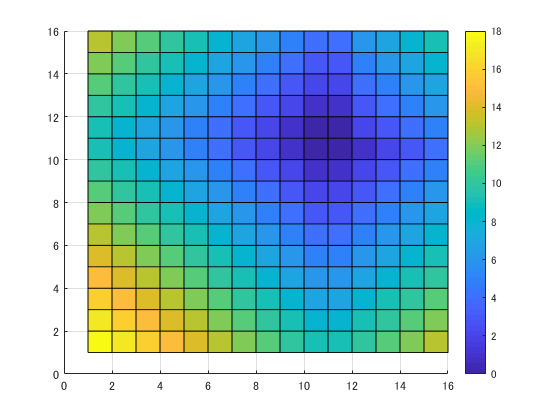

[x,y]=meshgrid(1:1:16,1:1:16);
surf(x,y,contour_map)
colorbar
view(2)

最短経路算出

歩数MAPから次に進む方向を決定

current_x = 1;
current_y = 1;
current_theta = 0;

goal_flag = 0;
int_little = max_length;


予約されたキーワード "classdef" が正しく使用されていません。

while 1

    %現在位置がゴールか判定
    for i = 1:1:4
        if (current_x == maze_goal(i,1)) & (current_y == maze_goal(i,2))
            goal_flag = 1;
            break
        end
    end
        
    if goal_flag == 1;
        break        
    end
    
    
    
    
end